# Trabajo Práctico 3: Ejercicio 1

Gp = tf([225/220], [250 1])

Gp =
 
   0.9091
  ---------
  250 s + 1
 
Continuous-time transfer function.
Model Properties


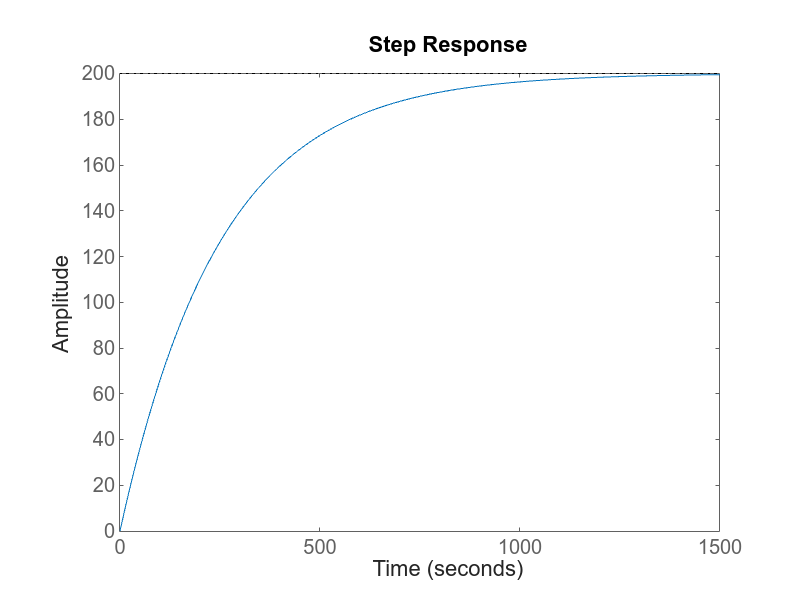

Ks =  0.00385;
opt = RespConfig;
opt.Amplitude = 220;
figure;
step(Gp, opt)

stepinfo(220 * Gp)

ans = struct with fields:
         RiseTime: 549.2516
    TransientTime: 978.0186
     SettlingTime: 978.0186
      SettlingMin: 180.9001
      SettlingMax: 199.8679
        Overshoot: 0
       Undershoot: 0
             Peak: 199.8679
         PeakTime: 1.8306e+03


## Control Lineal

Gp = tf([225/220], [250 1]);
Ks = 5/250;
Ka = 220/15;
Glanc = Gp * Ks * Ka;
[zla, pla, kla] = zpkdata(Glanc, 'v')


zla =

  0×1 empty double column vector



pla = -0.0040

kla = 0.0012

dcgain(Glanc)

ans = 0.3000

Mp = 0.1;
xeta = -log(Mp)/sqrt(pi^2 + log(Mp)^2)

xeta = 0.5912

ts = 900;
omega_nat = 4/(xeta * ts)

omega_nat = 0.0075

Kc = (2 * xeta * omega_nat - abs(pla)) / kla

Kc = 4.0741

zero_pi = omega_nat^2/(kla * Kc)

zero_pi = 0.0116

s = tf('s');
Gc = Kc * (s + zero_pi)/s

Gc =
 
  4.074 s + 0.0471
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


Glc = feedback(Gc * Ka * Gp, Ks)

Glc =
 
       61.11 s + 0.7065
  ---------------------------
  250 s^2 + 2.222 s + 0.01413
 
Continuous-time transfer function.
Model Properties


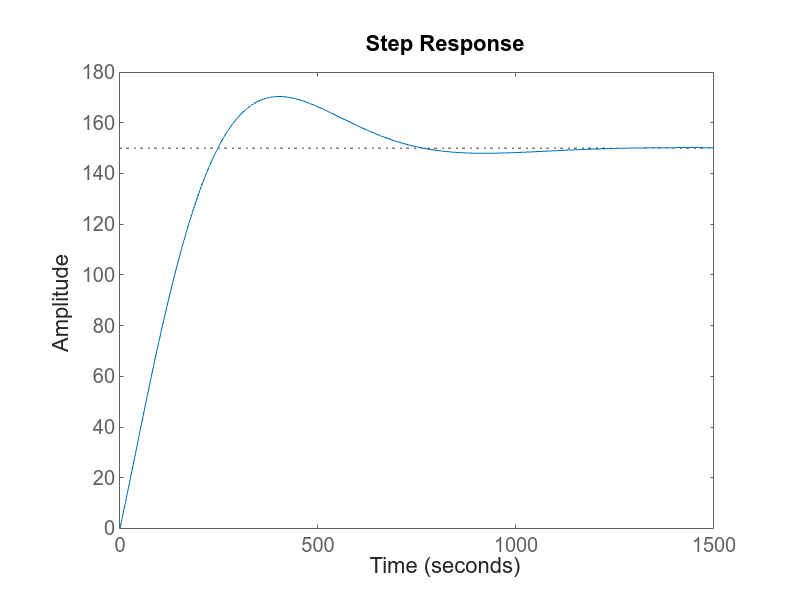

Vref = (150*5)/250;
step(Vref * Glc)

% salida controlada:
% sisotool(planta * actuador, controlador, sensor, Vref)
% salida sensor:
% sisotool(planta * actuador * sensor, controlador, 1, Vref)
% sisotool(Gp * Ka, Gc, Ks, Vref)